# Filtros: Ahora es personal

## Importar datos

load("../../Utils4SP/Datasets/S9_Filtros.mat");

## Filtro Savitzky-Golay

- Aplicar S.G. 

- Calcular los coeficientes y guardarlos

- Aplicar promedio móvil

- Comparar en tiempo y en frecuencia

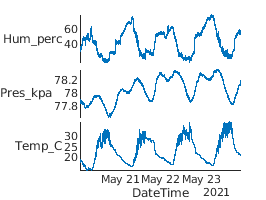

figure
stackedplot(atmosfera(:,["DateTime" "Hum_perc" "Pres_kpa" "Temp_C"]),'XVariable',"DateTime");

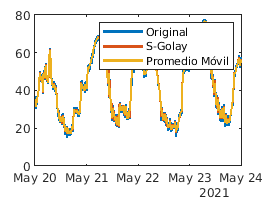


atmosfera_sg=sgolayfilt(atmosfera{:,["Hum_perc" "Pres_kpa" "Temp_C"]},2,101);
atmosfera_movmean=movmean(atmosfera{:,["Hum_perc" "Pres_kpa" "Temp_C"]},101);

figure
plot(atmosfera.DateTime,[atmosfera.Hum_perc atmosfera_sg(:,1) atmosfera_movmean(:,1)],'LineWidth',2)
legend("Original","S-Golay","Promedio Móvil")

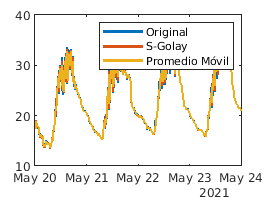


figure
plot(atmosfera.DateTime,[atmosfera.Temp_C atmosfera_sg(:,3) atmosfera_movmean(:,3)],'LineWidth',2)
legend("Original","S-Golay","Promedio Móvil")

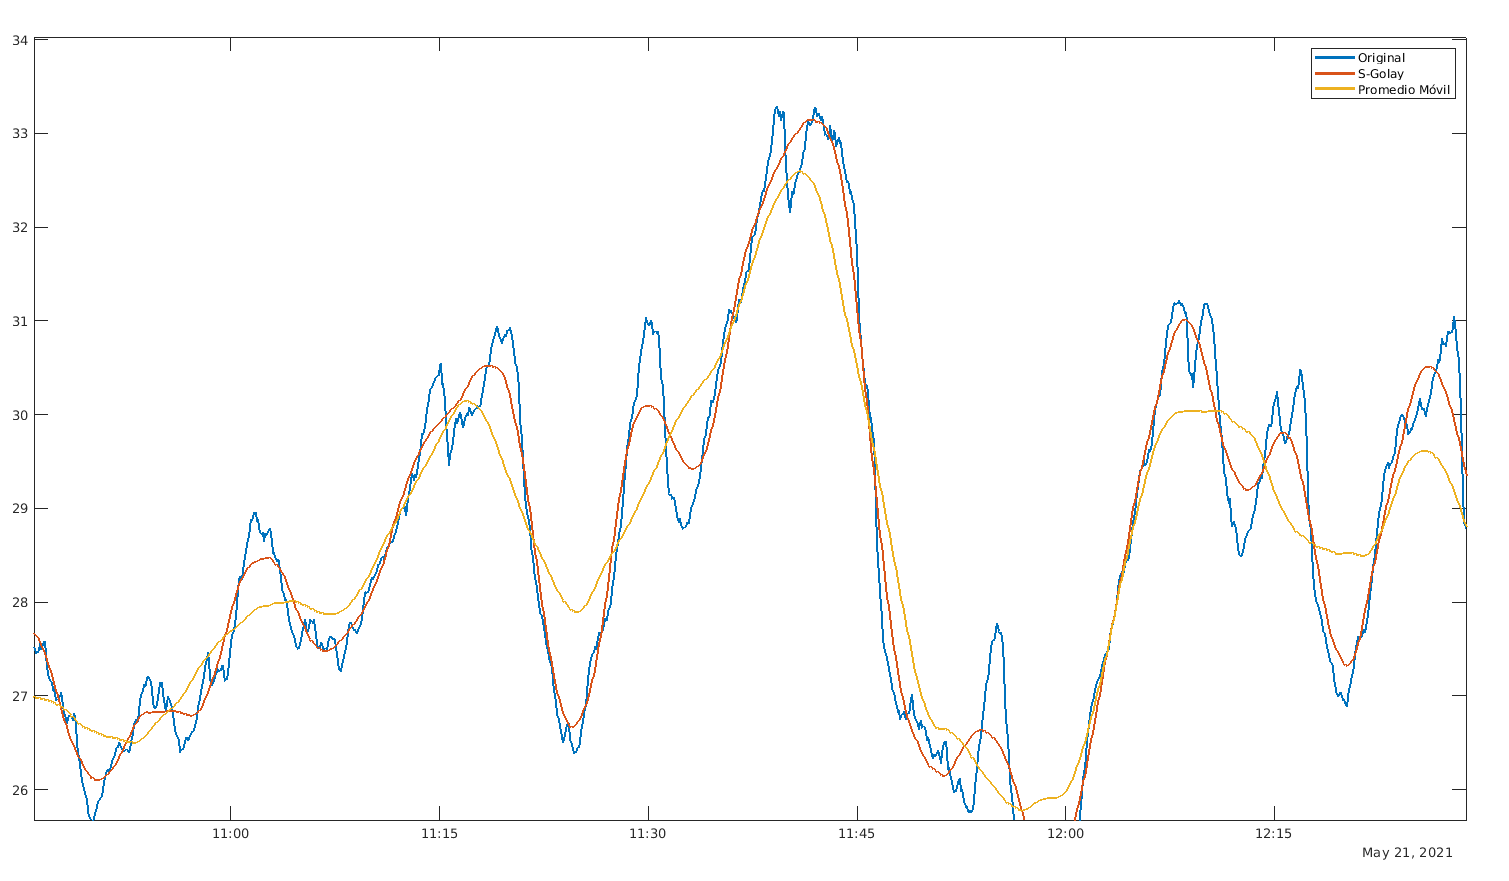

Acercamiento a las transiciones del campo de temperatura. Se observa que el filtro SGolay conserva los valles y picos, mientras que el promedio móvil los rechaza.

## Diseño de filtros

- Diseñar filtros con design filt

- Paso alto (FIR IIR) y paso bajo (FIR IIR) 

- Visualizar con FV tool

- Sacarles los coeficientes con TF

Revisar el audio del buho con el espectrograma

- Rediseñar los filtros pasa altos y pasabajos para rechazar "Unas señales"

- Visualizar el audio del buho filtrado

low_pass=designfilt;

designfilt('lowpassfir','PassbandFrequency',0.45,'StopbandFrequency',0.55,'PassbandRipple',0.1,'StopbandAttenuation',60);


high_pass=designfilt;

designfilt('highpassfir','StopbandFrequency',0.45,'PassbandFrequency',0.55,'StopbandAttenuation',60,'PassbandRipple',0.1);


Visiualizacion de filtros

%fvtool(low_pass)
%fvtool(high_pass)
LP_coeff=tf(low_pass);
HP_coeff=tf(high_pass);

Mirar al buho

buho_ch1=buho(:,1);
N_spec=numel(buho_ch1)/100;

spectrogram(buho_ch1,rectwin(N_spec),[],[],fs_buho,'yaxis')

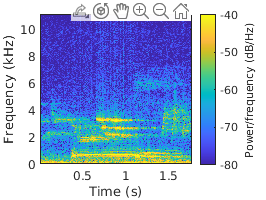

caxis([-80 -40])

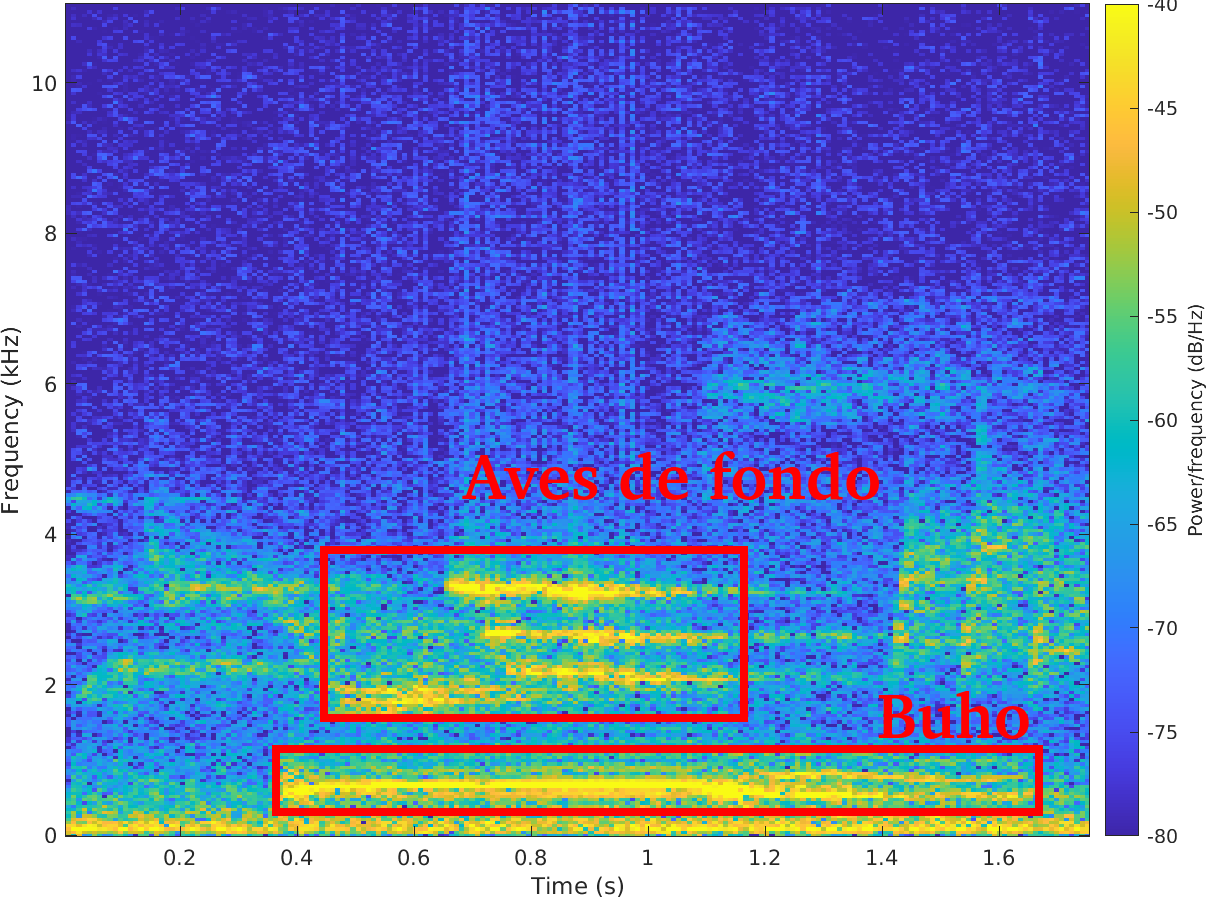

- Hacer un paso alto para quitar al buho

- Hacer un paso bajo para quitar a las aves

high_pass_buho=designfilt;

designfilt('highpassfir','StopbandFrequency',1500,'PassbandFrequency',1600,'StopbandAttenuation',60,'PassbandRipple',0.1,'SampleRate',22050);


low_pass_buho=designfilt;

designfilt('lowpassfir','PassbandFrequency',1500,'StopbandFrequency',1600,'PassbandRipple',0.1,'StopbandAttenuation',60,'SampleRate',22050);


Visualizacion

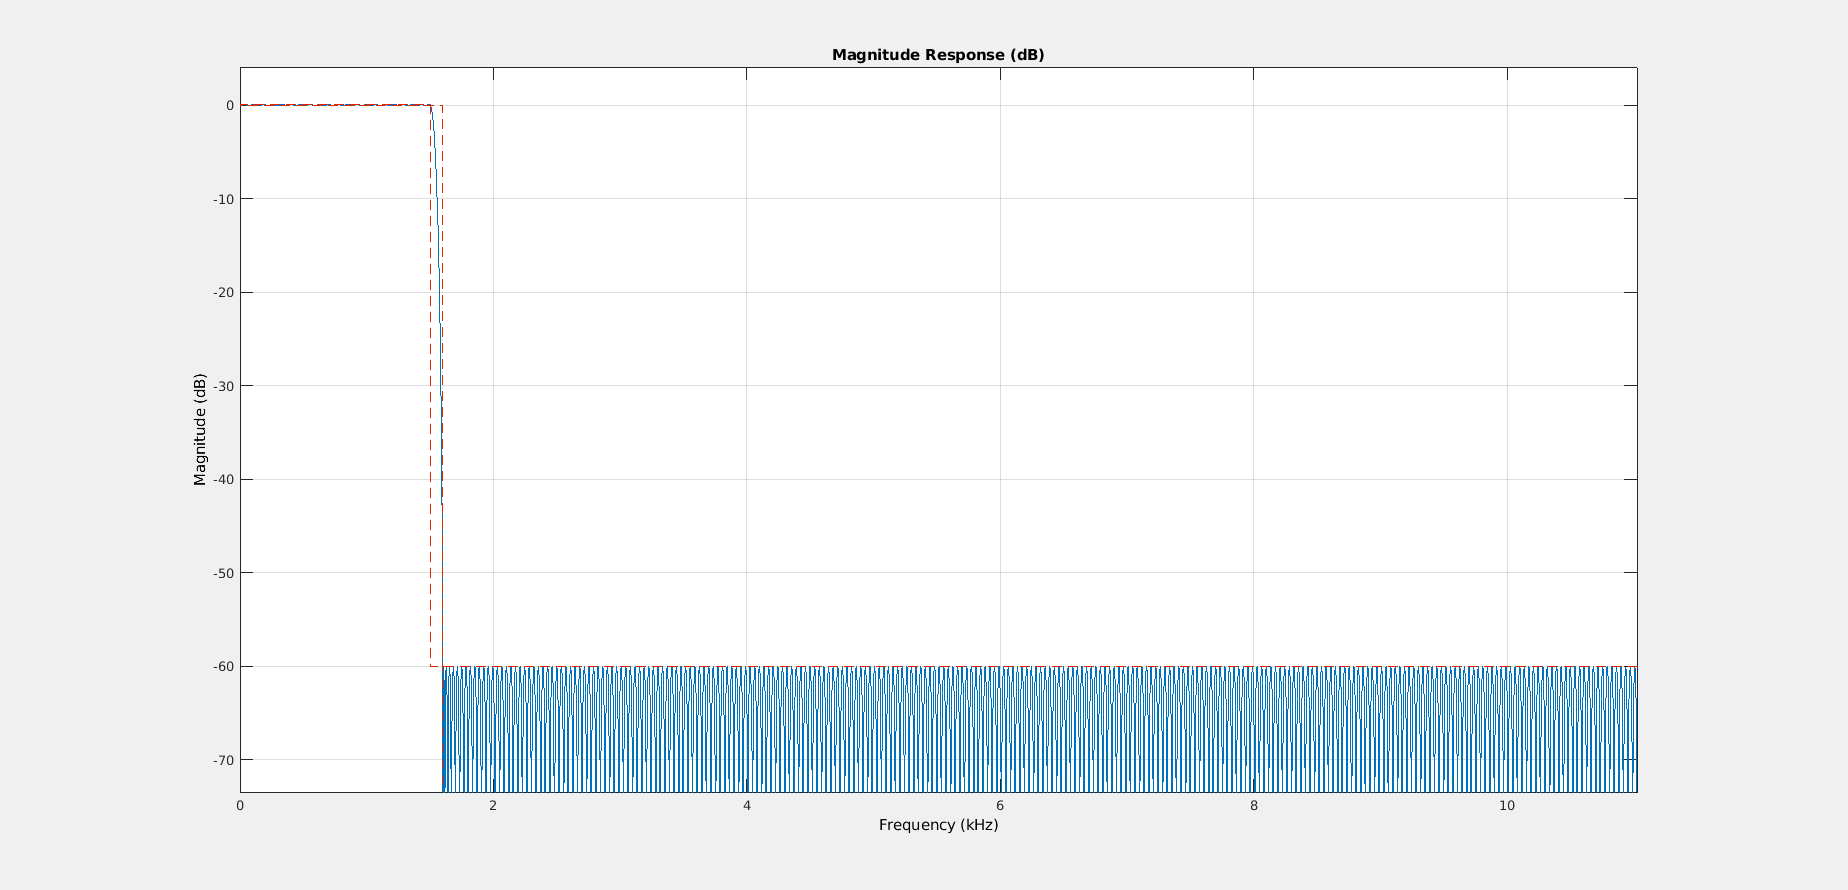

fvtool(high_pass_buho)

fvtool(low_pass_buho)

Filtrar la señal del buho con los filtros previos

Usar filter

buho_LP=filter(low_pass_buho,buho_ch1);
buho_HP=filter(high_pass_buho,buho_ch1);


Visualización antes y después del filtrado

figure
spectrogram(buho_LP,rectwin(N_spec),[],[],fs_buho,'yaxis')

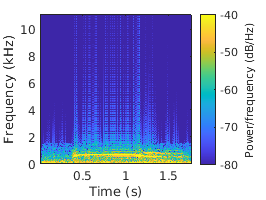

caxis([-80 -40])


figure
spectrogram(buho_HP,rectwin(N_spec),[],[],fs_buho,'yaxis')

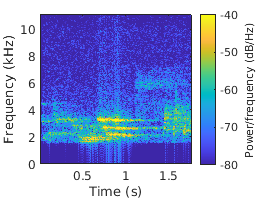

caxis([-80 -40])

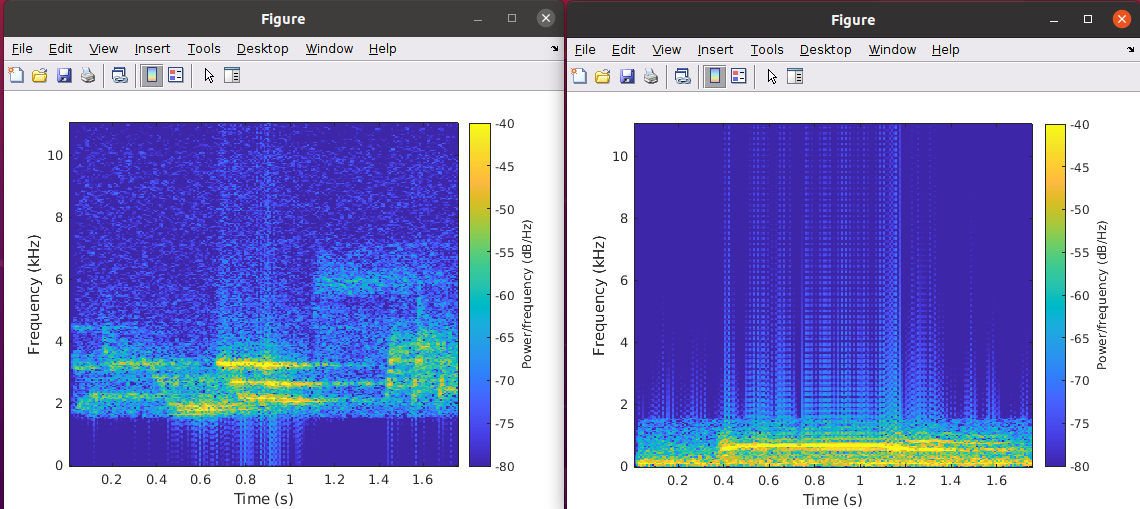

Izquierda: Filtro paso alto que elimina al buho// Derecha: Filtro paso bajo que elimina a las aves de fondo.

Escuchar

sound(buho_HP,fs_buho)
sound(buho_LP,fs_buho)